## **Session Data**

### **KingKong.01898**

- Premininary data collecting on 02/05/2020, **with perturbation**

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1910 = SessionScan(1898);

Loading raw FT and WAM...
FT High Sample...
WAM High Sample...
Trialfy...
  05%...  10%...  15%...  20%...  25%...  30%...  35%...  40%...  45%...  50%...  55%...  60%...  65%...  70%...  75%...  80%...  85%...  90%...  95%...  100%...  100%  FINISHED!


% trial count on each combo
taskScanTrials(ss1910);

FT: 10N, Dist: 0.05m, trials: 29 / 36
FT: 10N, Dist: 0.10m, trials: 29 / 32
FT: 20N, Dist: 0.05m, trials: 30 / 151
FT: 20N, Dist: 0.10m, trials: 30 / 45


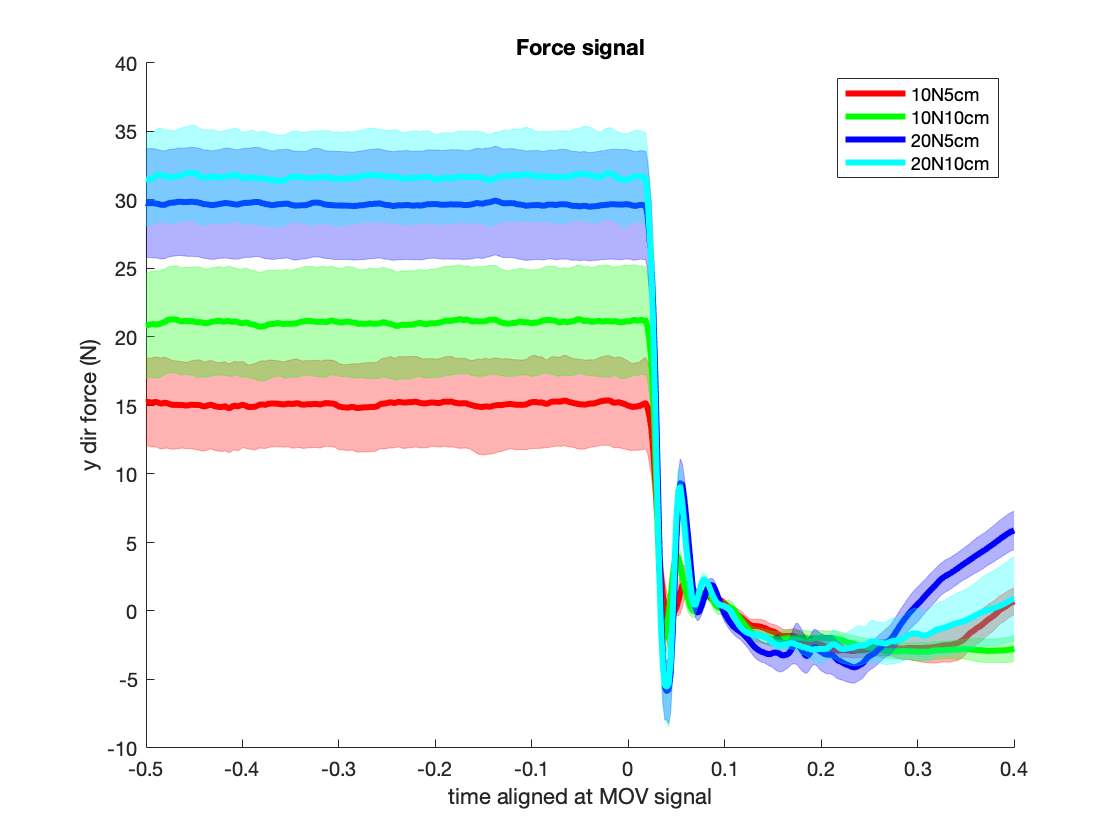

% figures of mean trial
axhf = plotMeantrialForce(ss1910);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


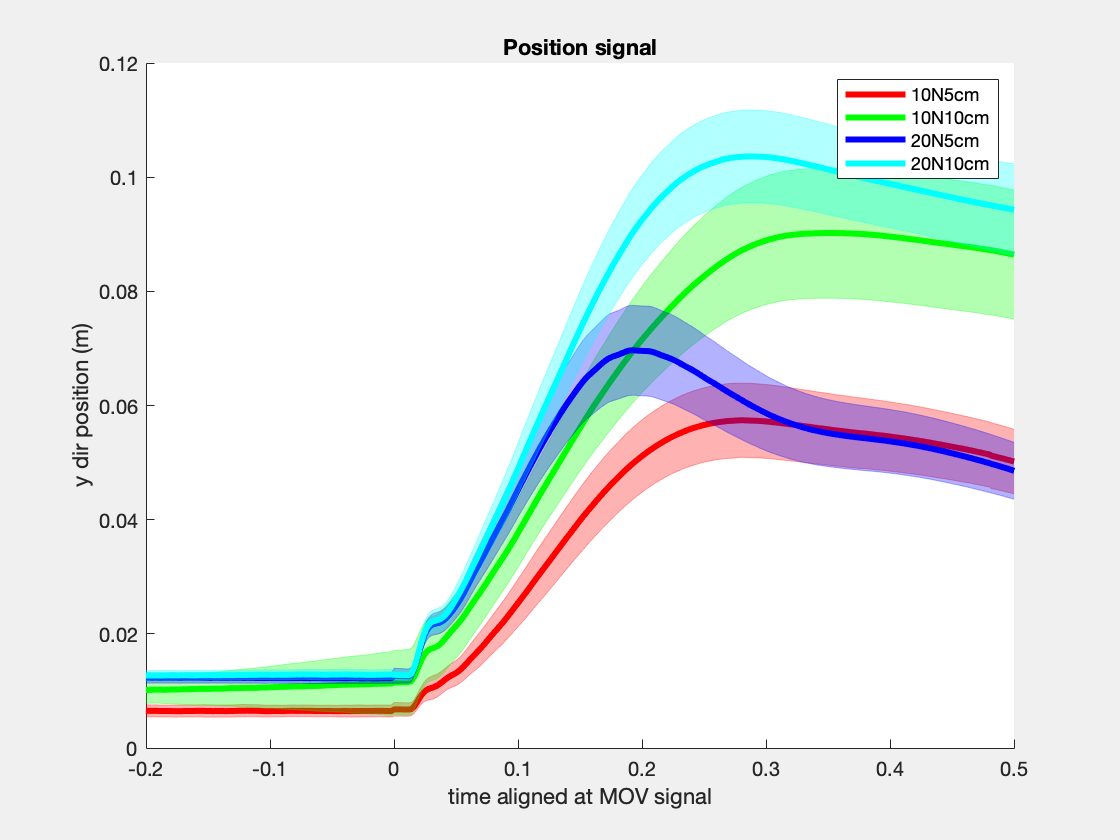

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


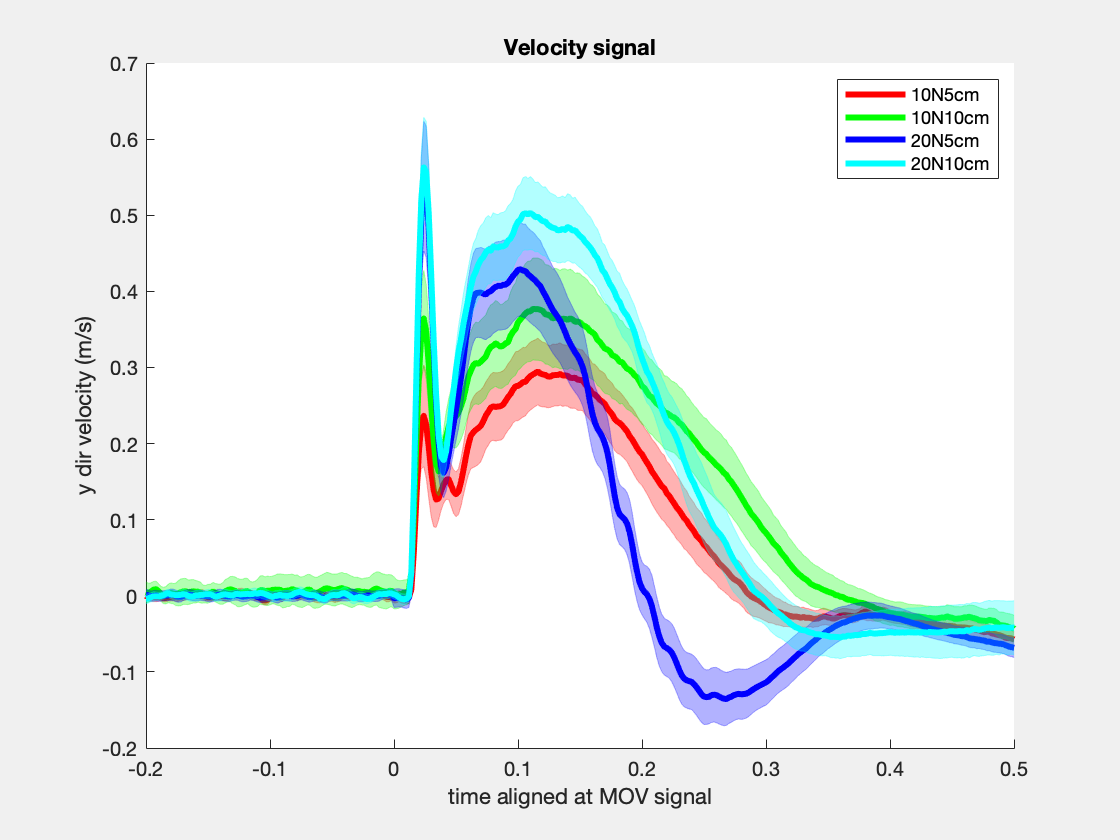

[axhp, axhv] = plotMeantrialPosVel(ss1910);

### **KingKong.01910**

- Preliminary data collecting on 02/09/2020, no perturbation

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1910 = SessionScan(1910);

Loading raw FT and WAM...
FT High Sample...
WAM High Sample...
Trialfy...
  05%...  10%...  15%...  20%...  25%...  30%...  35%...  40%...  45%...  50%...  55%...  60%...  65%...  70%...  75%...  80%...  85%...  90%...  95%...  100%...  100%  FINISHED!


% trial count on each combo
taskScanTrials(ss1910);

FT: 10N, Dist: 0.05m, trials: 30 / 31
FT: 10N, Dist: 0.10m, trials: 36 / 39
FT: 20N, Dist: 0.05m, trials: 30 / 541
FT: 20N, Dist: 0.10m, trials: 30 / 33


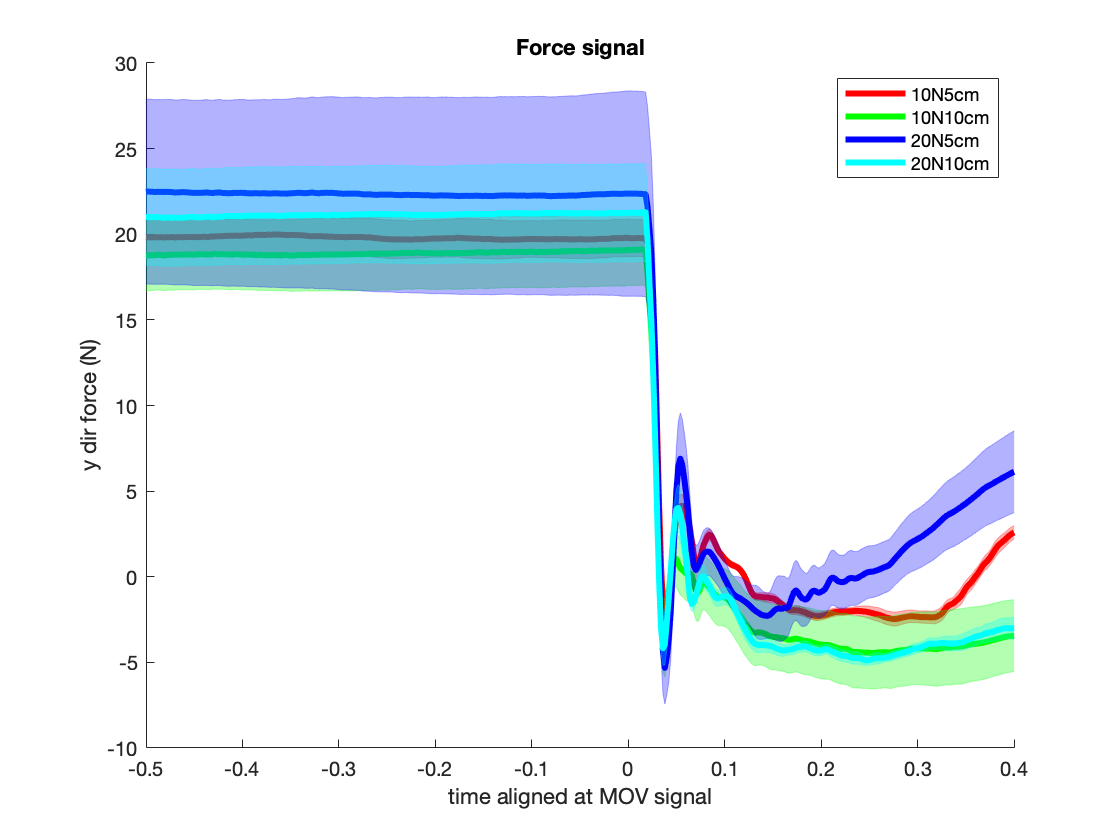

% figures of mean trial
axhf = plotMeantrialForce(ss1910);

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


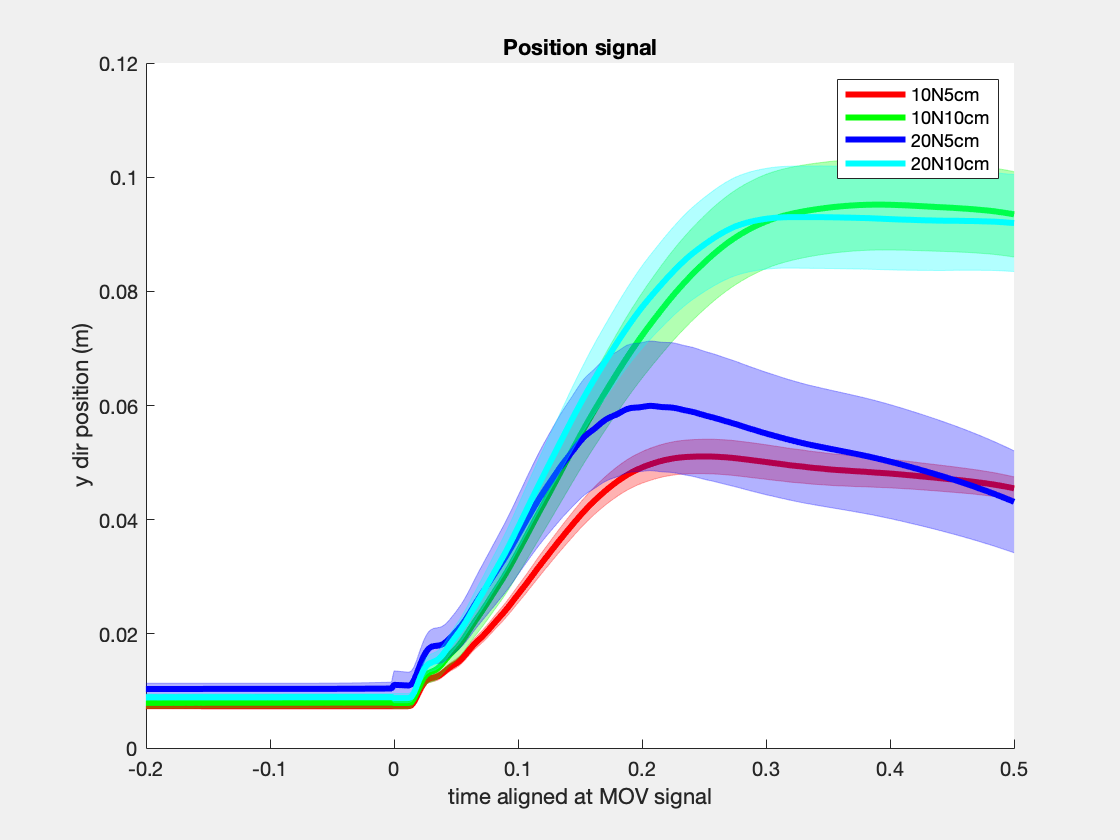

Enter function Resample;


Enter function Resample;


Enter function Resample;


Enter function Resample;


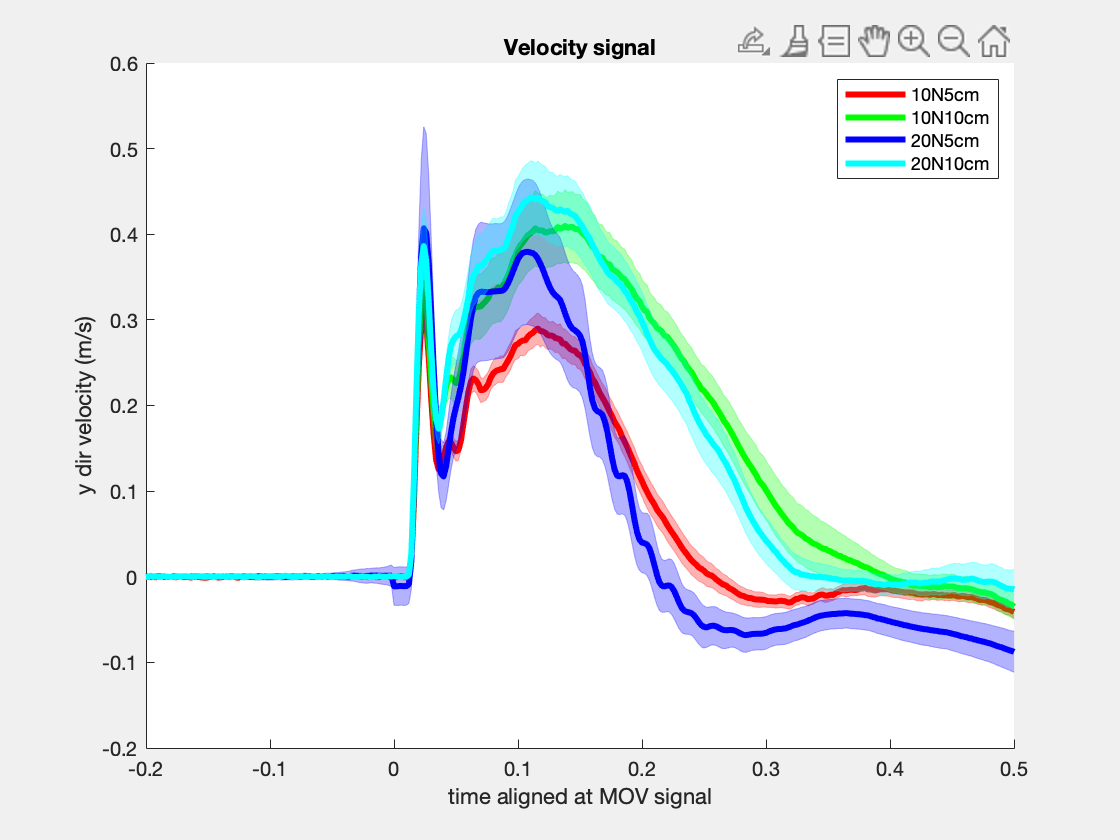

[axhp, axhv] = plotMeantrialPosVel(ss1910);

## Sanity Check certain session:

Sanity check should include: 

- Trial finish condition (color label each trial sucess/failure);   - Just see how the subject works on trials;

- Force baseline plot. - See if force baseline has changed significantly during trials. If exist, means force measurement are erroneous; 

- Original task curves on specific task. - To check each trial and the trial variance. (Q: how to see each trial according to their line?)

% specify session
ssnum = 1910;
% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
% 1. Trial Finish Condition
axh = eval(fObjectName).plotTaskTrialFinish()
% 2. Force Baseline Plot

% 3. Original Curve on each trial